clc
close all

% Constants
J = 0.0005 + 0.0015 + (0.2*0.2794^2) % Moment of Inertia [kgm^2]

J = 0.0176

Km = 0.0401; % Motor Constant [Nm/Amp]
Rm = 19.2; % Motor Resistance [Ohms]
Kg = 33.3; % Gear Ratio

% Proportianal Gains
Kp = [10 20 5 10 10 10];

% Derivative Gains
Kd = [0 0 0 1 -1 -0.5];

% Closed Loop System
omega_n = sqrt((Kp .* Kg * Km)./(J * Rm));
zeta = (Kg^2 * Km^2 + Kd .* Kg * Km)./(2 * sqrt(Kp .* Kg * Km *J * Rm))

zeta =     0.4196    0.2967    0.5933    0.7337    0.1054    0.2625


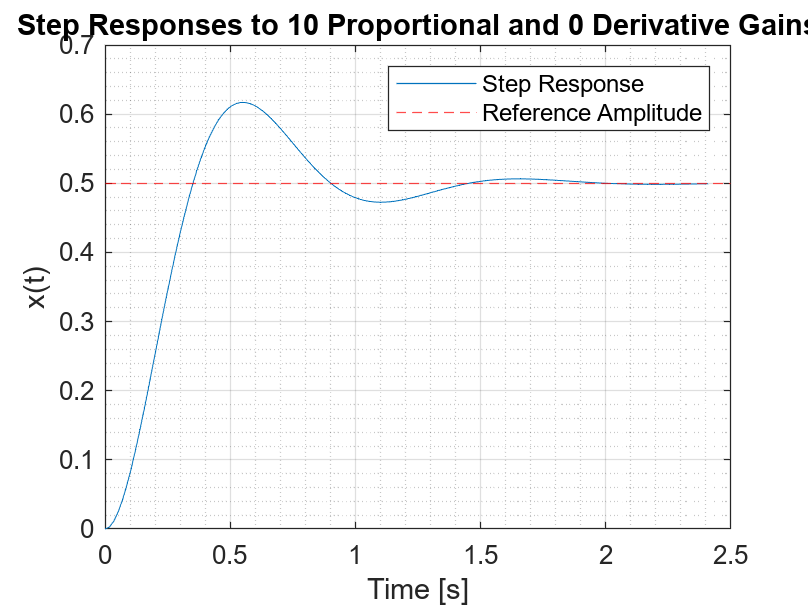

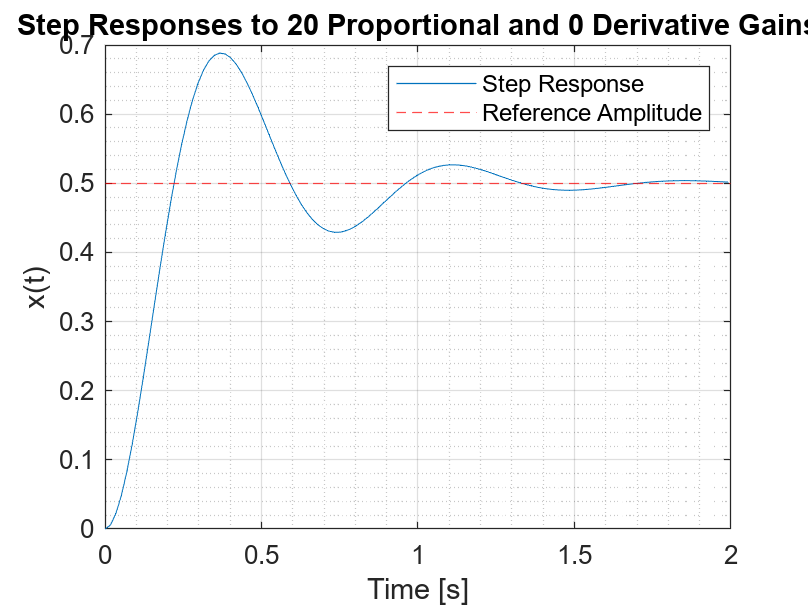

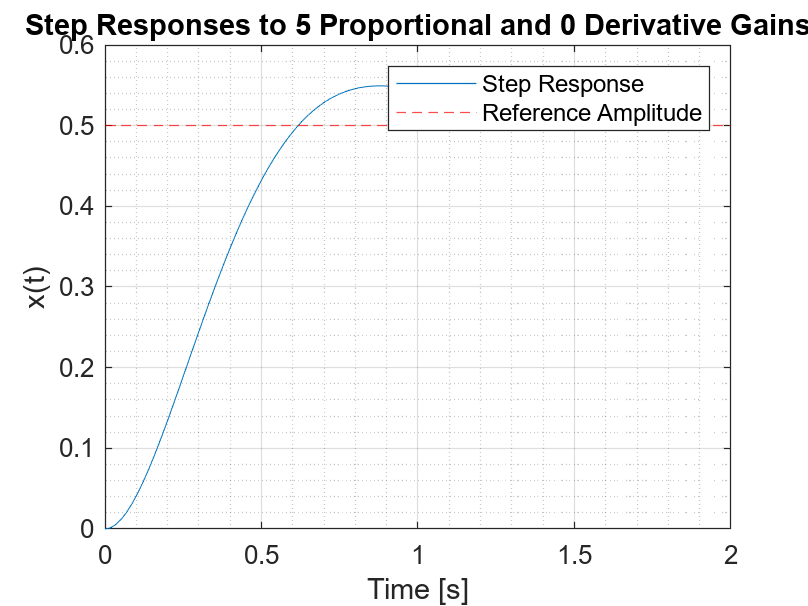

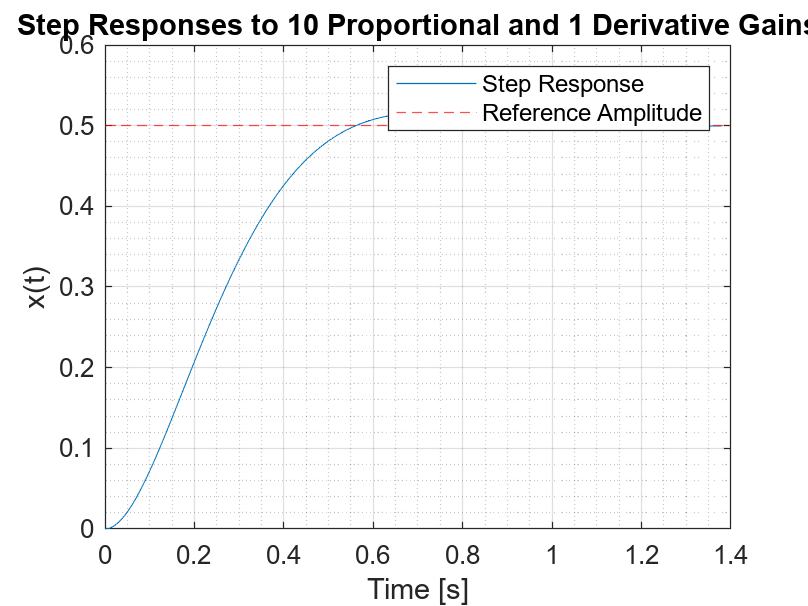

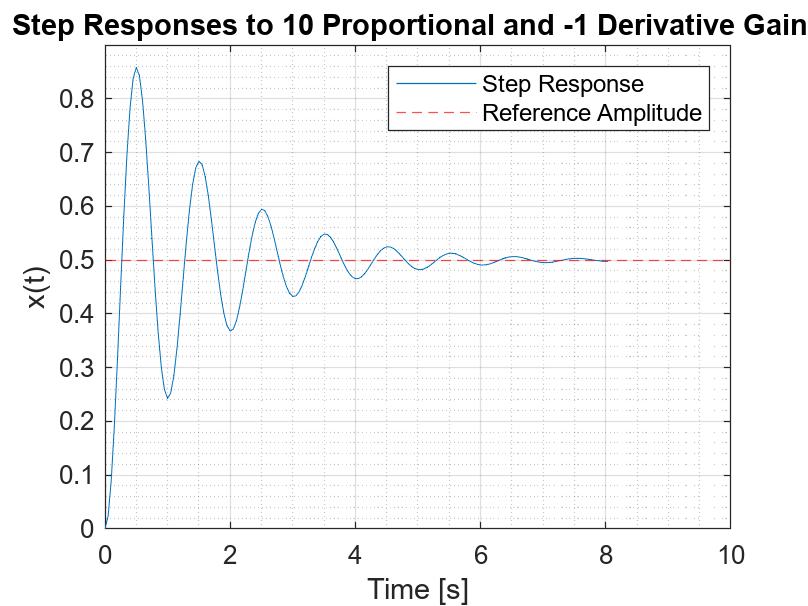

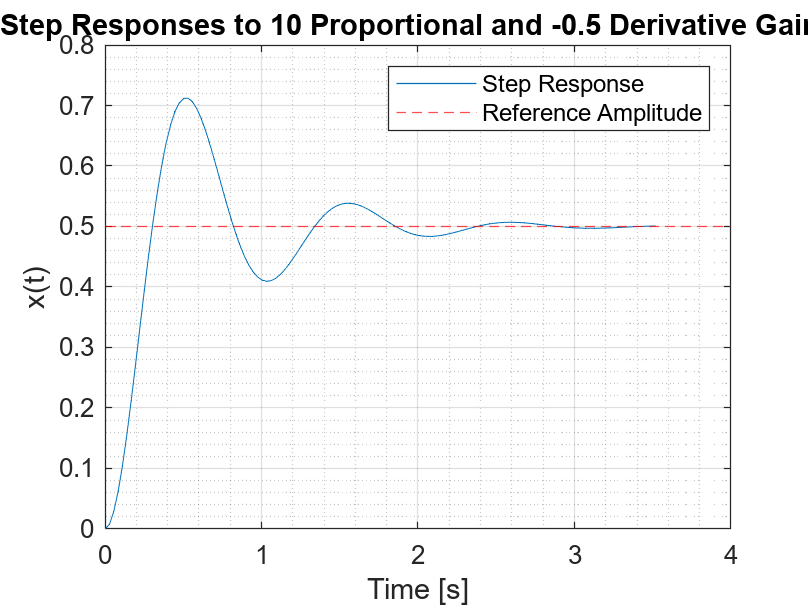


num = zeros(1,6);
den = zeros(3,6);
sysTF = zeros(1,6);

for i = 1:6
    num(i) = omega_n(i)^2;
    den(:,i) = [1 2*omega_n(i)*zeta(i) omega_n(i)^2];
    sysTF = tf(num(i),den(:,i)');
    [x,t] = step(0.5*sysTF);
    figure
    plot(t,x)
    hold on
    yline(0.5,'--r')
    hold off
    grid on;grid minor
    xlabel('Time [s]')
    ylabel('x(t)')
    title(strcat('Step Responses to'," ", string(Kp(i)), ' Proportional and '," ", string(Kd(i)), ' Derivative Gains'))
    legend('Step Response','Reference Amplitude')
end




% <20% Overshoot and 5% Settling Time <1s
Kp2 = 13.45;
Kd2 = 1.04;

omega_n2 = sqrt((Kp2 * Kg * Km)/(J * Rm));
zeta2 = (Kg^2 * Km^2 + Kd2 * Kg * Km)/(2 * sqrt(Kp2 * Kg * Km *J * Rm)) + 0.3

zeta2 = 0.9435

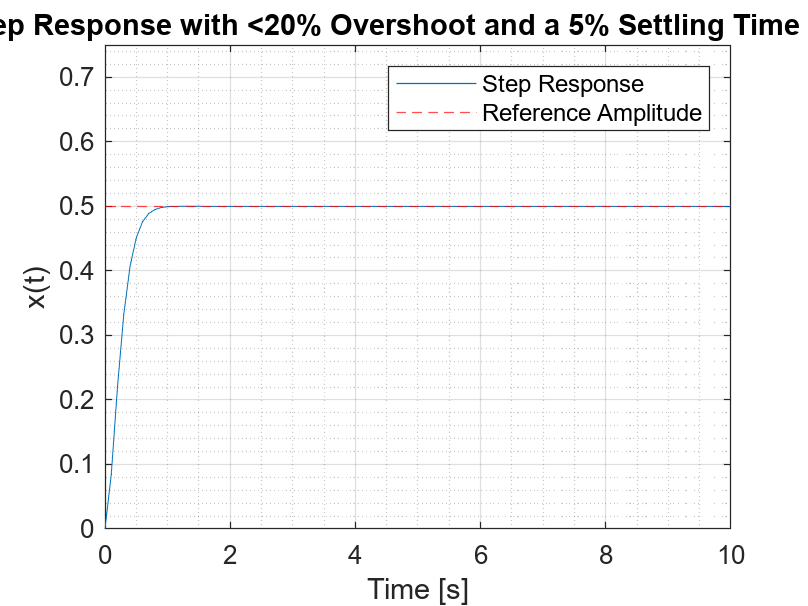

num2 = omega_n2^2;
den2 = [1 2*omega_n2*zeta2 omega_n2^2];
sysTF2 = tf(num2,den2);
[x2,t2] = step(0.5*sysTF2,0:0.1:10);
plot(t2,x2)
hold on
grid on; grid minor
yline(0.5,'--r')
ylim([0 0.75])
xlabel("Time [s]")
ylabel('x(t)')
legend('Step Response','Reference Amplitude')
title('Step Response with <20% Overshoot and a 5% Settling Time < 1s ')
hold off

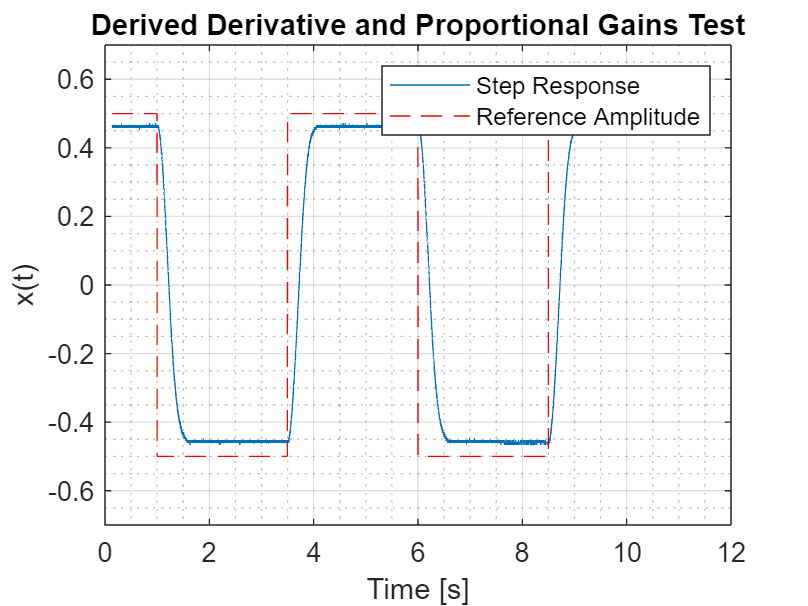


% Read Hardware Data
dataset1 = readmatrix('datatest1');
dataset2 = readmatrix('datatest2');

% Extract Useful Data
time1 = dataset1(:,1);
time2 = dataset2(:,1);
position1 = dataset1(:,2);
position2 = dataset2(:,2);
reference1 = dataset1(:,6);
reference2 = dataset2(:,6);

% Convert ms to s
time1 = time1./1000;
time1 = time1 - fix(time1(1));
time2 = time2./1000; 
time2 = time2 - fix(time2(1));

% Derived Data
plot(time1,position1);
grid on; grid minor
hold on
plot(time1,reference1,'--r')
ylabel('x(t)')
xlabel('Time [s]')
ylim([-0.7 0.7])
title('Derived Derivative and Proportional Gains Test')
legend('Step Response','Reference Amplitude')
hold off

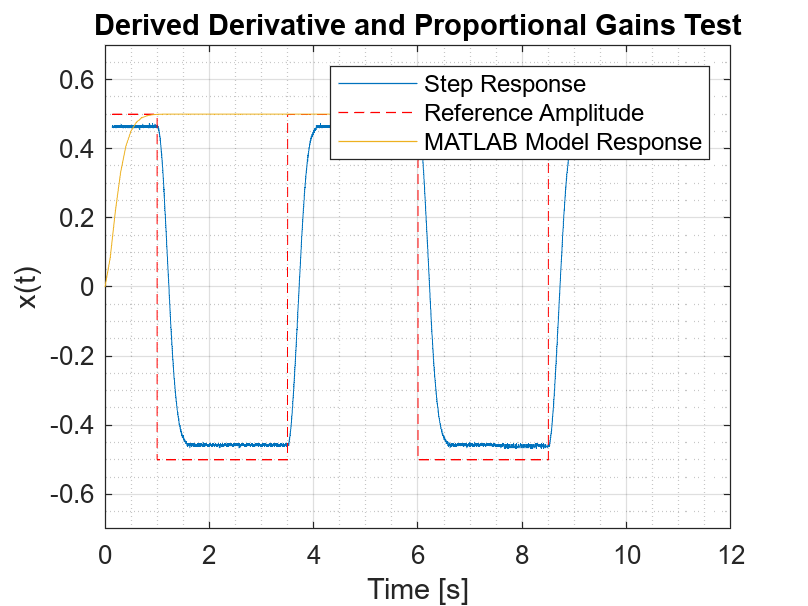


% Derived MATLAB vs Actual
plot(time1,position1);
grid on; grid minor
hold on
plot(time1,reference1,'--r')
ylabel('x(t)')
xlabel('Time [s]')
ylim([-0.7 0.7])
plot(t2,x2)
title('Derived Derivative and Proportional Gains Test')
legend('Step Response','Reference Amplitude','MATLAB Model Response')
hold off

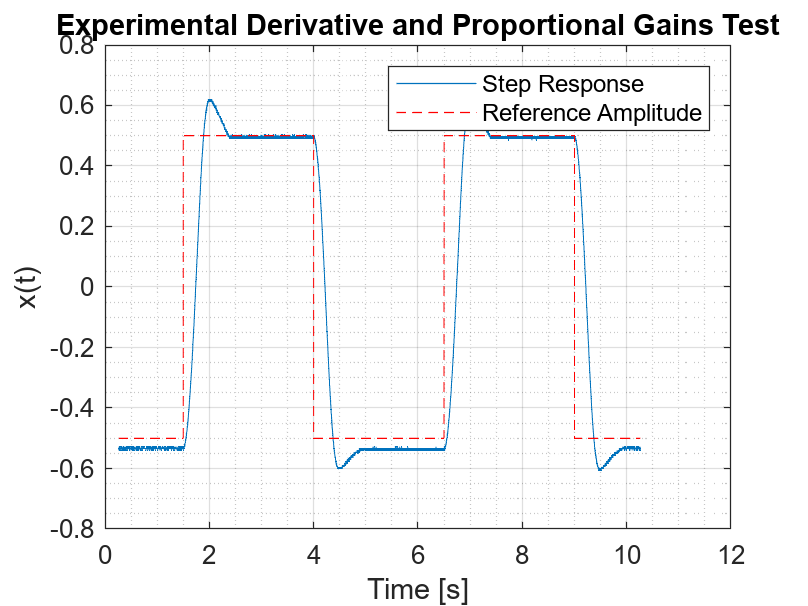


% Experimental Data
plot(time2,position2)
grid on; grid minor
hold on
plot(time2,reference2,'--r')
ylabel('x(t)')
xlabel('Time [s]')
title('Experimental Derivative and Proportional Gains Test')
legend('Step Response','Reference Amplitude')
hold off